# **2.086 Final Project Report:**

# **"Charles River Depth Analysis"**

Elissa C. Ito, Emily A. Scherer, Viviana Rivera

Daniel Frey

May 20, 2021

### **1. Team **Members** and Roles:**

We all be collaborated on the different aspects of our project but we assigned a key person to each of the main categories of work to allow for better organization.

**Elissa Ito:**

- Acquiring depth data for Charles River (communication with MIT Sea Grant)

- Transforming the data into a matrix representing the x,y, and z (depth) values

- Refining data using interpolation

**Viviana Rivera:**

- Creating the part of the function that models the probability of getting mud on the sail in a certain area of the river due to sail height and depth of river

- Documenting progress for a more detailed report

**Emily Scherer:**

- Creating the part of the function that models the probability of capsizing due to wind conditions

- Performing integration to obtain volume of Charles River

### 2. Project Report Summary: 

Our team decided to study some of the sailing-related intricacies of the Charles River. We were granted access to the MIT Sea Grant Charles River depth data which we used to perform integration to calculate the overall volume of the Charles River (from the Harvard Bridge up to the Longfellow Bridge) and to create a function that models the probability of capsizing a sailboat and getting mud on the sail. 

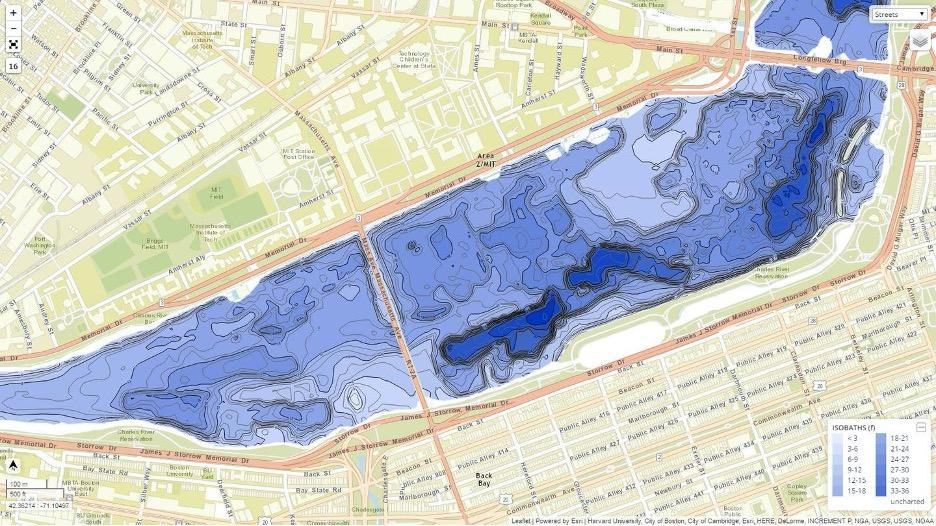

**Figure 1.**  Charles River Depth Data (MIT Sea Grant). 

[https://mit.sea-grant.net/maps/charleschart/](https://mit.sea-grant.net/maps/charleschart/)

We broke down this probability function into two separate parts:

- Analyzing inputs such as wind speed and wind angle, and then correlating them to a probability of capsizing a sailboat under certain conditions (we will be using real-life data from the MIT sailing team practices).

- Taking the height of the sail used by MIT sailing team and the depth data of the area the team uses to practice to calculate the probability of getting mud on the sail (meaning contact with the ground of the River) during practice. 

The product of these two gives us our predicted probability for capsizing the sailboat and getting mud on the sail.

### **3.** Project Descriptions/Details and Implementations/Codes**:**

A. Our first task was to interpret the Charles River data we were given by the MIT Sea Grant. We did this by loading the data and its settings, creating coordinates with x,y, and depth values, and plotting them to make sure they gave an accurate depiction of the river.

       Loading the data and its settings:

clear all;
clf;
fid=fopen("basin_esri_grid.asc",'r'); %open file (must be in same folder)
tline = fgets(fid);%gets a new line in the file
[A] = sscanf(tline, '%s%f');%finds the strings and floats in line, places them in array
ncols = A(end);%A has 6 numbers: the first 5 is ncols and the last is 4000, the ncols value

tline = fgets(fid);%similar processes for other set values
[A] = sscanf(tline,'%s%f');
nrows = A(end);

tline = fgets(fid);
[A] = sscanf(tline,'%s%f');
xllcorner = A(end);

tline = fgets(fid);
[A] = sscanf(tline,'%s%f');
yllcorner = A(end);

tline = fgets(fid);
[A] = sscanf(tline,'%s%f');
cellsize = A(end); %we still need to figure out what dimensions this is in - our best guess is it's a degree but unclear

tline = fgets(fid);
[A] = sscanf(tline,'%s%f');
nodata_value = A(end); %when data is not collected (i.e. outside of the edges of the river), nodata_value is put in place

%from this point on the asc files are just floats of the depth
data = ones(4000,1514); %with dimensions 4000x1514
for i = 1:1514
    tline = fgets(fid);
    data(:,i) = sscanf(tline,'%f');% copying asc file into a matrix called data
end

no_data_cells = 0;
for i = 1:4000
    for j = 1:1514
        if data(i,j) == nodata_value
            data(i,j) = NaN;%replacing the nodata_value with NaN - hoping this will make future calculations error easier to spot
            no_data_cells = no_data_cells+1;
        end
    end
end

%depth data is in meters!!!! - this inference can be made by the depth diagram
max_depth = max(max(data));
min_depth = min(min(data));

tline = fgets(fid);%checking that we're at the end of the file
fclose(fid) ;%closing file

   Creating Coordinates:

x_vals = ones(1,4000*1514);
y_vals = ones(1,4000*1514);
for i = 1:1514 %x_vals must have 1514 "1"s then 1514 "2"s and so on (but then adjusted to longitude)
    x_vals(1,(i-1)*4000+1:(i)*4000) = xllcorner+cellsize*i;
end

current_index = 1;
for i = 1:1514 %y_vals must repeatedly go from 4000 to 1 (but then adjusted to latitude)
    for j = 1:4000
        y_vals(1,current_index) = yllcorner+cellsize*j;
        current_index = current_index + 1;
    end
end

z_vals = data(:)'; %z_vals are just the values in data made into a horz array
x_y_z = [x_vals; y_vals; z_vals;];

    Plotting:

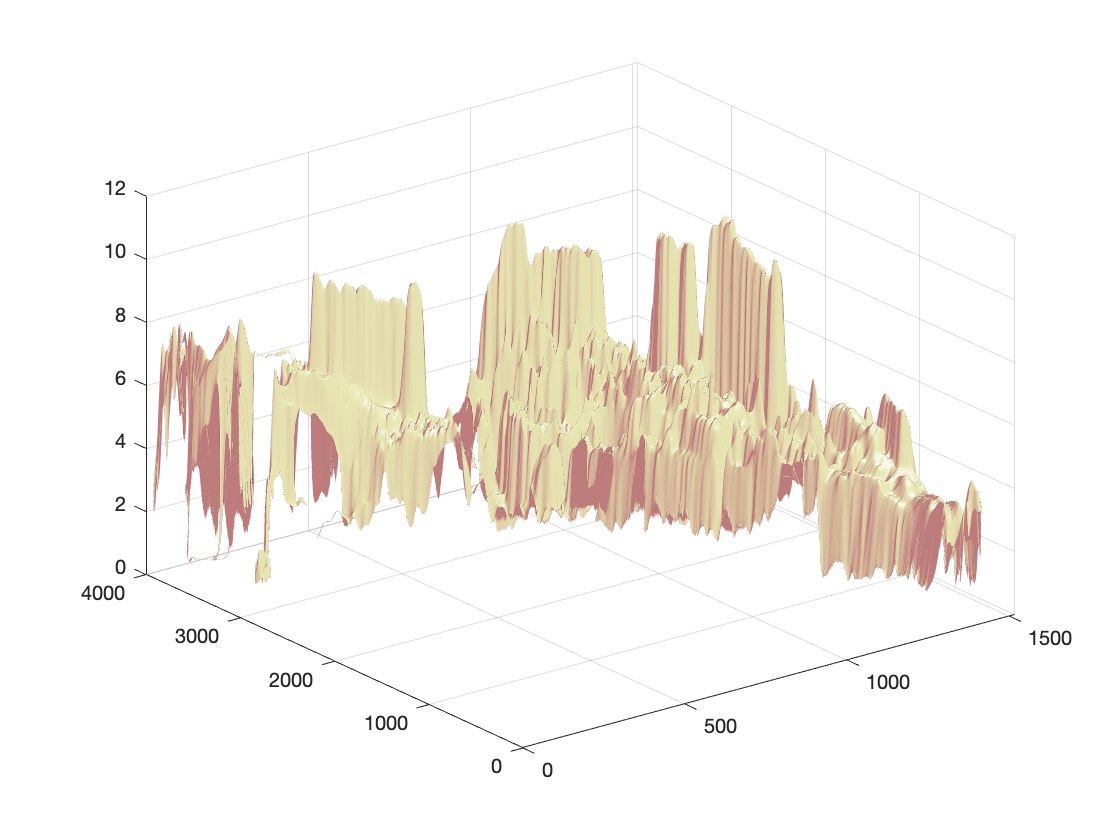

surfl(data) % to visualize what the floats in the original asc file look like
colormap(pink)
shading interp

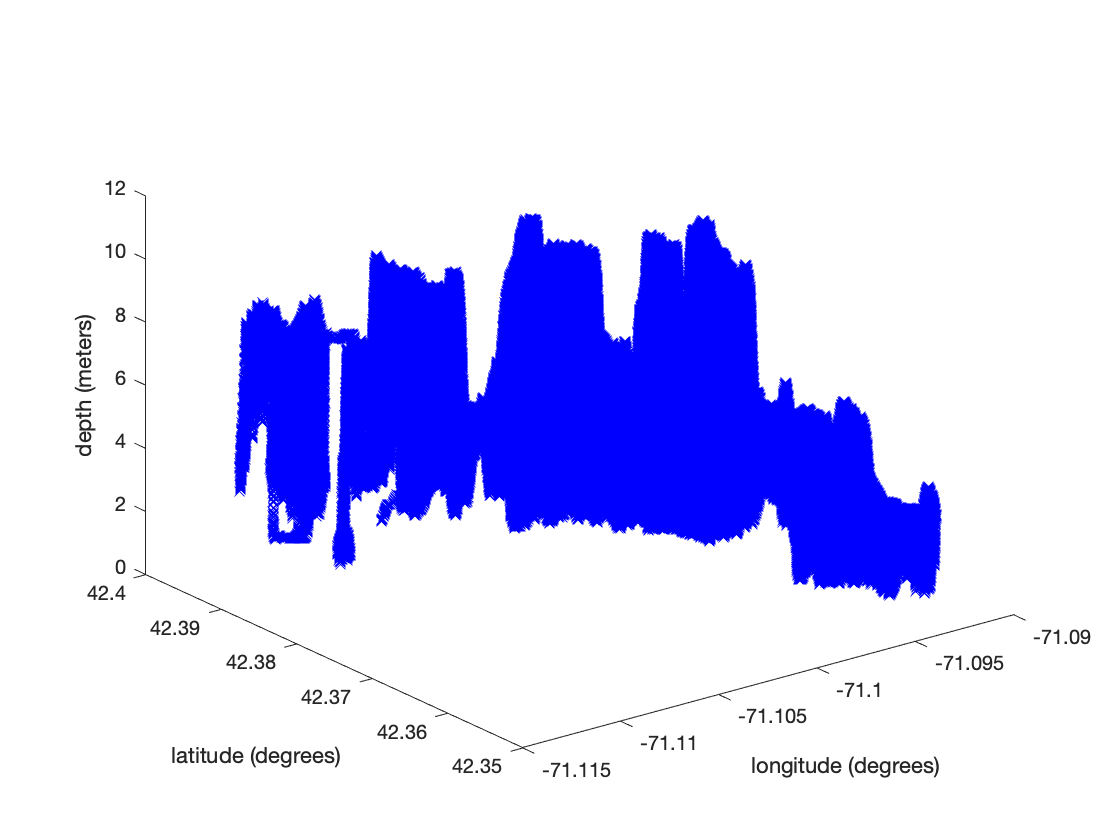

plot3(x_y_z(1,:),x_y_z(2,:),x_y_z(3,:),'bx') %plotting our copied data (with arbitrary x and y values)
xlabel('longitude (degrees)')
ylabel('latitude (degrees)')
zlabel('depth (meters)')

B. Our second task was to find the volume of the Charles River by executing 3D interpolation and double integration on the values we had previously extracted.

Interpolation:

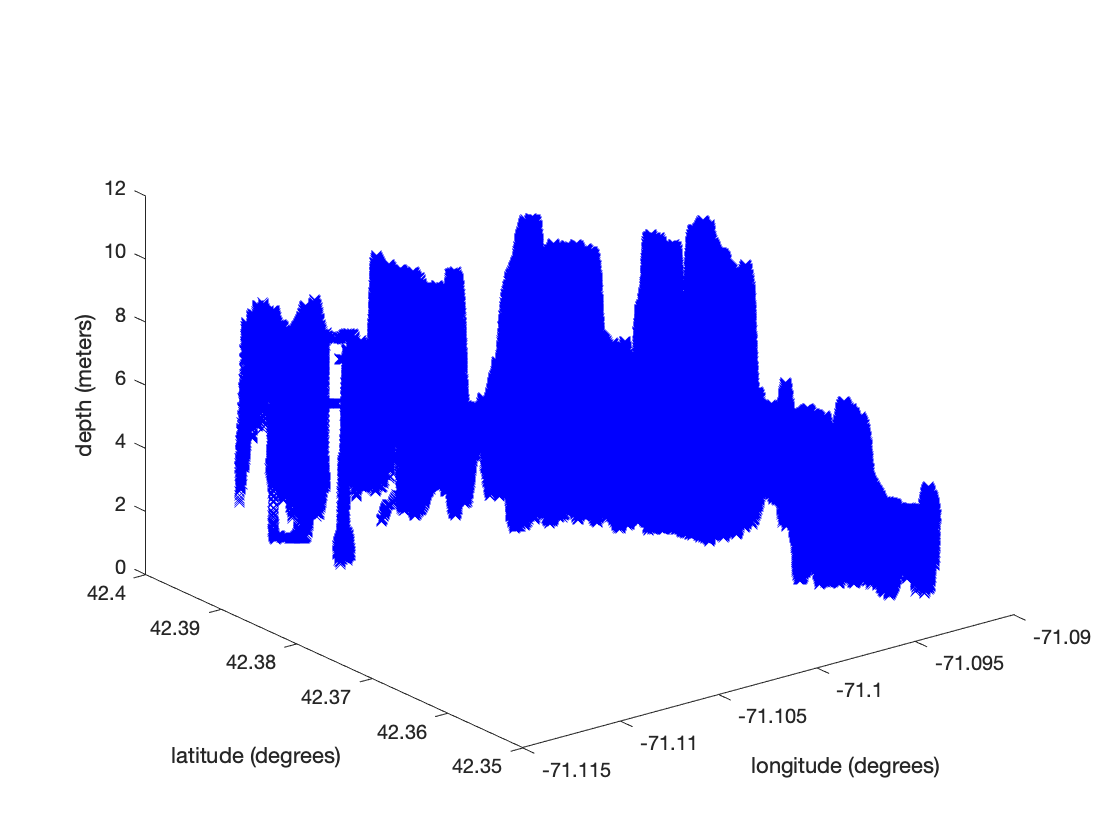

% we will interpolate in the direction that z matrix is linearized - i.e.
% top down moving left to right
relevant_x = [];
relevant_y = [];
relevant_z = [];
for i=1:length(y_vals)-1
    if ~isnan(z_vals(i))
        relevant_x(end+1) = x_vals(i);
        relevant_y(end+1) = y_vals(i);
        relevant_z(end+1) = z_vals(i);
    end
end
intpl_xvals = relevant_x;
intpl_yvals = relevant_y;
intpl_zvals = relevant_z;
for i = 1:length(relevant_x)-1
    newx = relevant_x(i)+0.5*cellsize;
    newy = relevant_y(i)+0.5*cellsize;
    zintpl = relevant_z(i)+((relevant_z(i+1)-relevant_z(i))/(relevant_x(i+1)-relevant_x(i)))*(newx-relevant_x(i));
    intpl_zvals(end+1) = zintpl;
    intpl_yvals(end+1) = newy;
    intpl_xvals(end+1) = newx;
end
intpl_x_y_z = [intpl_xvals; intpl_yvals; intpl_zvals;];
plot3(intpl_x_y_z(1,:),intpl_x_y_z(2,:),intpl_x_y_z(3,:),'bx') %plotting our copied data (with arbitrary x and y values)
xlabel('longitude (degrees)')
ylabel('latitude (degrees)')
zlabel('depth (meters)')

Integration:

% will perform double integration for pre-interpolation points
% must ignore all points with NaN z values
innerloop = [];
for i = 1:length(relevant_x)-1
    innerloop(end+1) = ((relevant_z(i+1)+relevant_z(i))/2)*abs(relevant_x(i+1)-relevant_x(i));
end
Volume = 0;
for i = 1:length(innerloop)-1
    Volume = Volume + ((innerloop(i+1)+innerloop(i))/2)*abs(relevant_y(i+1)-relevant_y(i));
end
Volume % in deg^2 * meters

Volume = 2.3787e-04

% converting deg to meters at this latitude is 111080.63808571725 m = 1 degree - value obtained from internet
Volume = Volume*111080.63808571725*111080.63808571725

Volume = 2.9351e+06

C. Our third task was to collect data on capsizes per practice and the practice conditions. We created a table where we recorded two main variables for three weeks of practice: wind speed, and difference between wind speed and gust speed. The greater the wind speed the higher the likelihood of capsize. The greater the difference between the gust speed and wind speed, the higher the likelihood of capsize. The gust speed itself is irrelevant, because capsizes happen when a sailor is surprised by a sudden burst of wind. If the wind velocity is already very high and the gust speed is only slightly greater, this would result in a less likely capsize than if the gust speed was the same magnitude but the regular wind speed is much lower. We plan to collect this data through the app called *Sailflow* which displays a forecast and active measurement of the these parameters on the Harvard bridge.

We then created a probability function that took all of these values as inputs and returned the calculated probabilty of capsizing according to the wind conditions during the practice. 

Table of Data

% data of type cell so I can make a table
Day = {'04/06';'04/07';'04/08';'04/09';'04/13';'04/14';'04/15';'04/16';'04/20';'04/21';'04/22';'04/23';'04/27';'04/28';'05/04';'05/05';'05/06'; '05/07';'05/11';'05/12';'05/13''05/14'};
Capsizes = {1;4;5;1;0;0;6;40;4;5;15;7;3;6;2;3;9;35;12;10;0}; % number of capsizes
WindSpeed = {5;7;10;6;3;5;11;20;10;6;15;14;8;10;6;10;11;18;8;10;5}; % in knots
GustSpeed = {10;14;15;12;5;6;16;28;15;11;22;20;14;16;12;16;17;25;15;13;8}; % in knots
table(Day,Capsizes,WindSpeed,GustSpeed)

ans = 21×5 table
       Day       Capsizes    WindSpeed    GustSpeed    Direction
    _________    ________    _________    _________    _________

    {'04/06'}     {[ 1]}      {[ 5]}       {[10]}       {[110]} 
    {'04/07'}     {[ 4]}      {[ 7]}       {[14]}       {[ 90]} 
    {'04/08'}     {[ 5]}      {[10]}       {[15]}       {[ 90]} 
    {'04/09'}     {[ 1]}      {[ 6]}       {[12]}       {[110]} 
    {'04/13'}     {[ 0]}      {[ 3]}       {[ 5]}       {[290]} 
    {'04/14'}     {[ 0]}      {[ 5]}       {[ 6]}       {[150]} 
    {'04/15'}     {[ 6]}      {[11]}       {[16]}       {[ 90]} 
    {'04/16'}     {[40]}      {[20]}       {[28]}       {[ 45]} 
    {'04/20'}     {[ 4]}      {[10]}       {[15]}       {[  0]} 
    {'04/21'}     {[ 5]}      {[ 6]}       {[11]}       {[180]} 
    {'04/22'}     {[15]}      {[

 %convert each cell structure to arrays
capsizes= cell2mat(Capsizes);
windspeed=cell2mat(WindSpeed);
gustspeed=cell2mat(GustSpeed);

Visualization of Data:

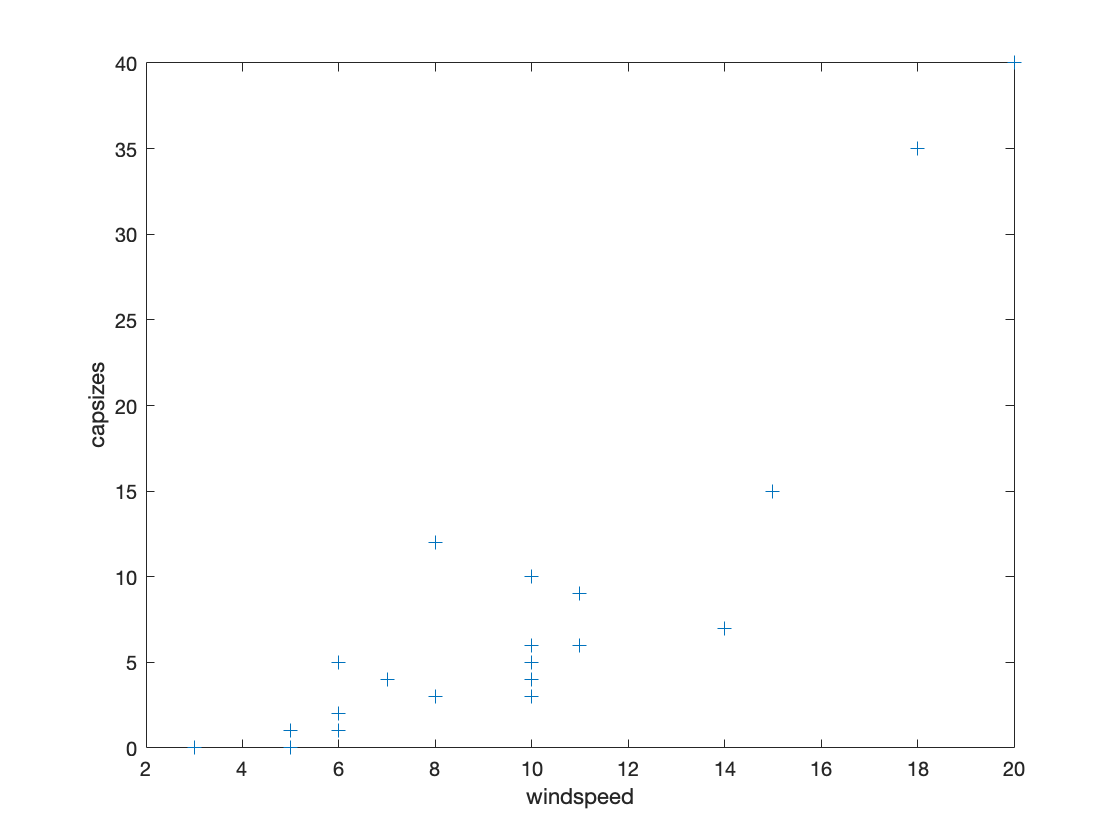

clf;
figure
plot(windspeed,capsizes,"+")
xlabel("windspeed")
ylabel("capsizes")

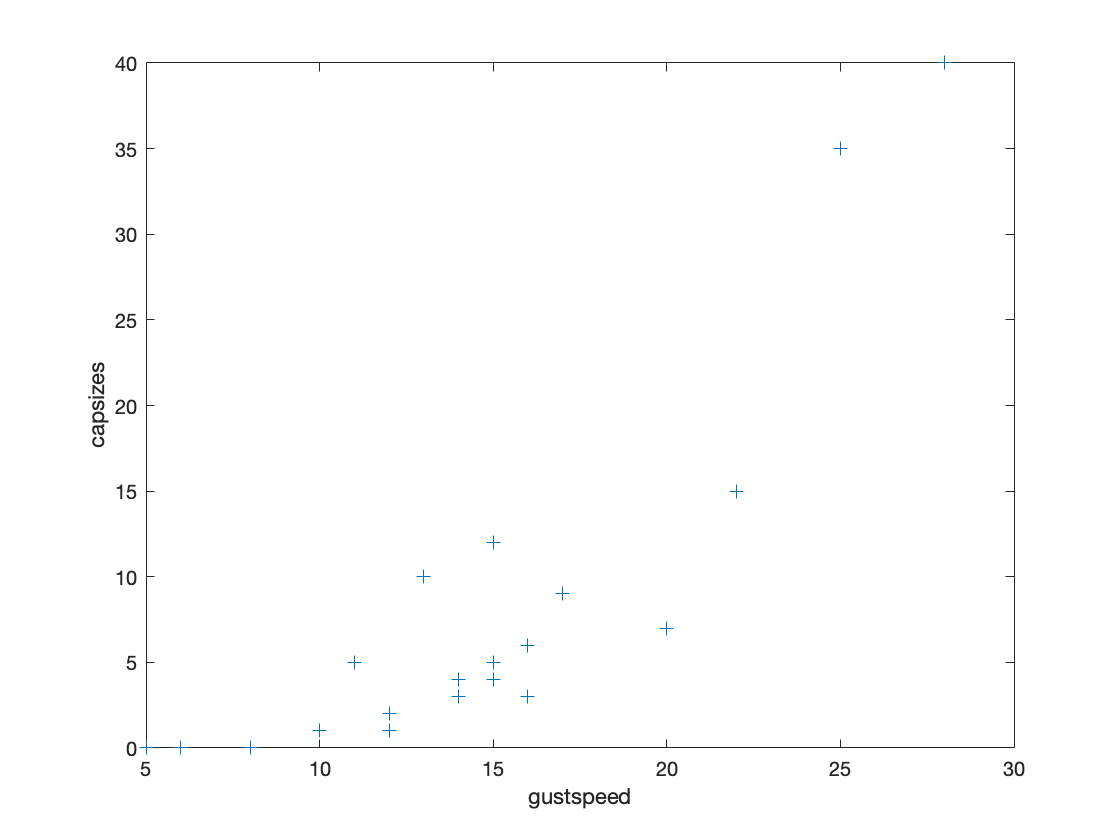

figure
plot(gustspeed,capsizes,"+")
xlabel("gustspeed")
ylabel("capsizes")

Models for Windspeed/Gustspeed vs Capsizes:

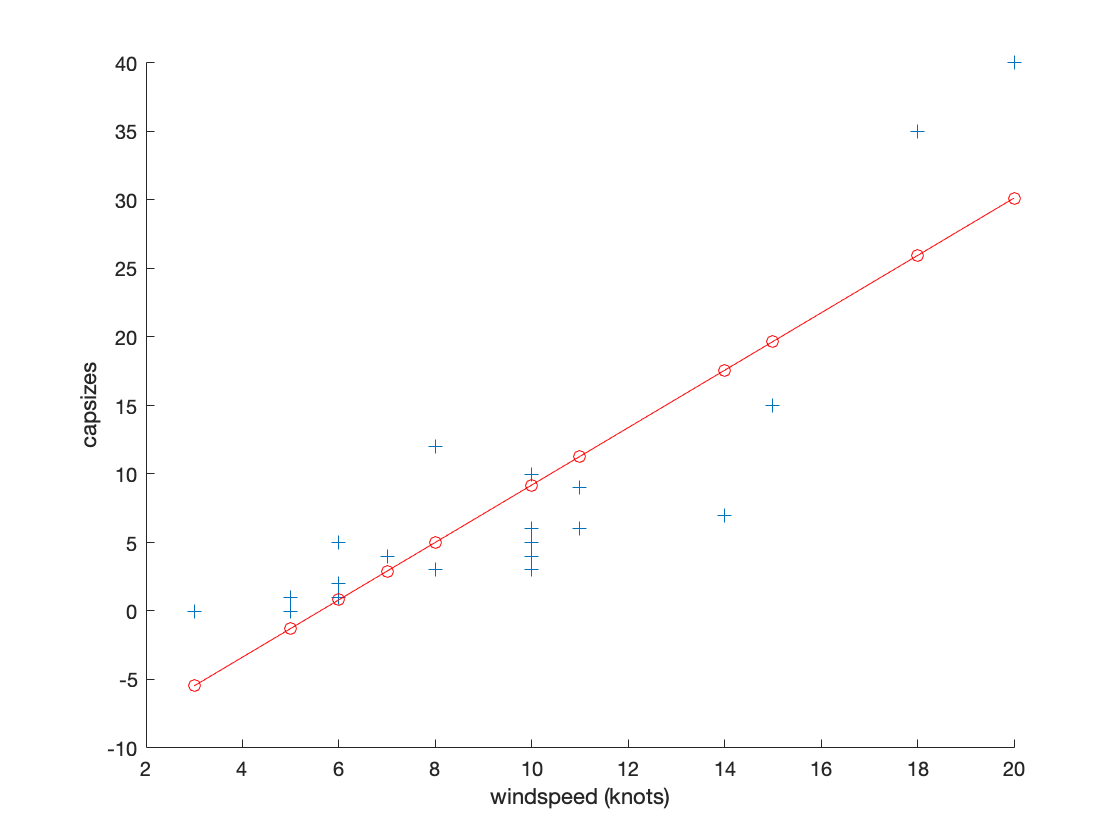

clf;
hold on;

%sorting data by windspeed
WSCS = zeros(length(windspeed),2);
WSCS(:,1) = windspeed;
WSCS(:,2) = capsizes;
WSCS = sortrows(WSCS);
WS = WSCS(:,1);
CS = WSCS(:,2);

%linear regression windspeed
X = [ones(length(WS),1) WS];
B_hat = inv(X'*X)*X'* CS;
capsizes_hat= X*B_hat;
plot(WS, CS, '+') % plot the data
hold on;
plot(WS, capsizes_hat, '-ro') % Plot the regression line
xlabel("windspeed (knots)")
ylabel("capsizes")

R2=1-sum(((X*B_hat) -CS).^2)/sum((CS-mean(CS)).^2)

R2 = 0.7559


%polynomial power 2 windspeed
figure;
X = [ones(length(WS),1) WS WS.^2];
[Q,R] = qr(X,0); % Compute the QR decomposition of X
B_hat = R \ (Q'* CS); % Compute the parameters of the regression eqn
capsizes_hat= X*B_hat;
plot(WS, CS, '+') % plot the data
hold on;
plot(WS, capsizes_hat, '-ro') % Plot the regression line
xlabel("windspeed (knots)")
ylabel("capsizes")
R2=1-sum(((X*B_hat) -CS).^2)/sum((CS-mean(CS)).^2)

R2 = 0.8930

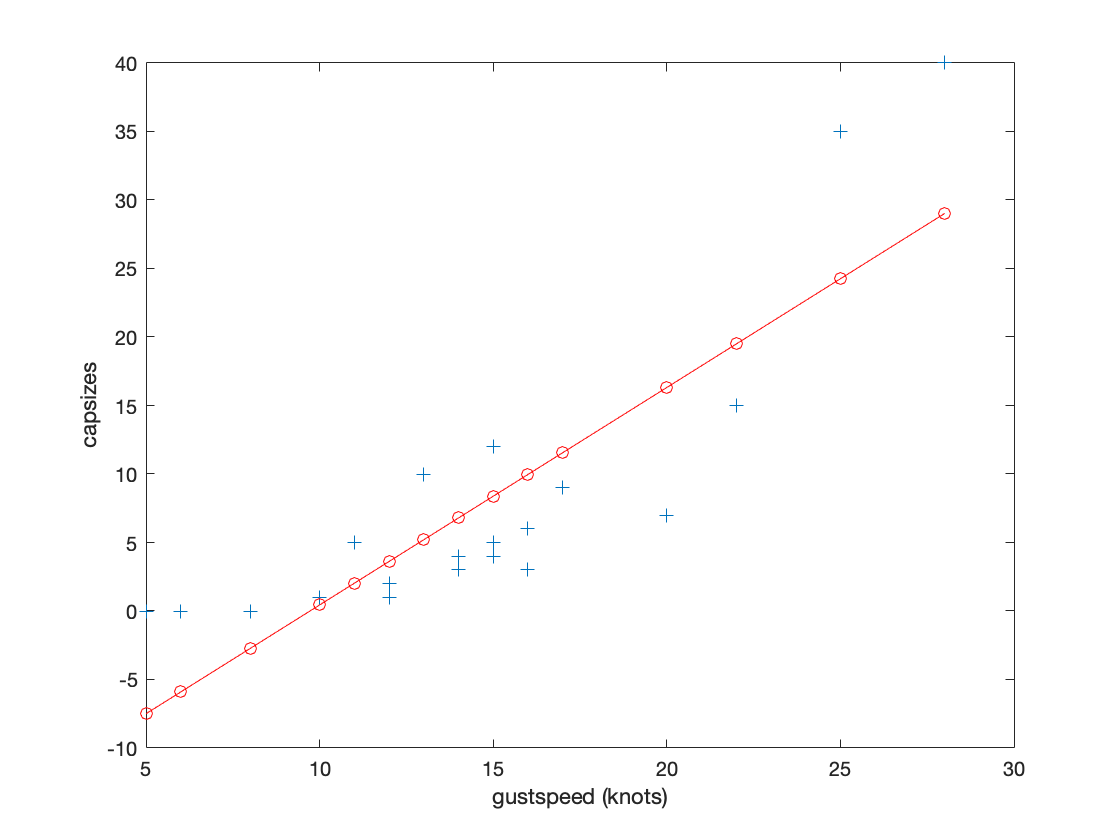


%sorting data by gustspeed
GSCS = zeros(length(gustspeed),2);
GSCS(:,1) = gustspeed';
GSCS(:,2) = capsizes';
GSCS = sortrows(GSCS);
GS = GSCS(:,1);
CS = GSCS(:,2);
%linear regression gustspeed
figure;
X = [ones(length(GS),1) GS];
B_hat = inv(X'*X)*X'* CS;
capsizes_hat= X*B_hat;
plot(GS, CS, '+') % plot the data
hold on;
plot(GS, capsizes_hat, '-ro') % Plot the regression line
xlabel("gustspeed (knots)")
ylabel("capsizes")

R2=1-sum(((X*B_hat) -CS).^2)/sum((CS-mean(CS)).^2)

R2 = 0.7185

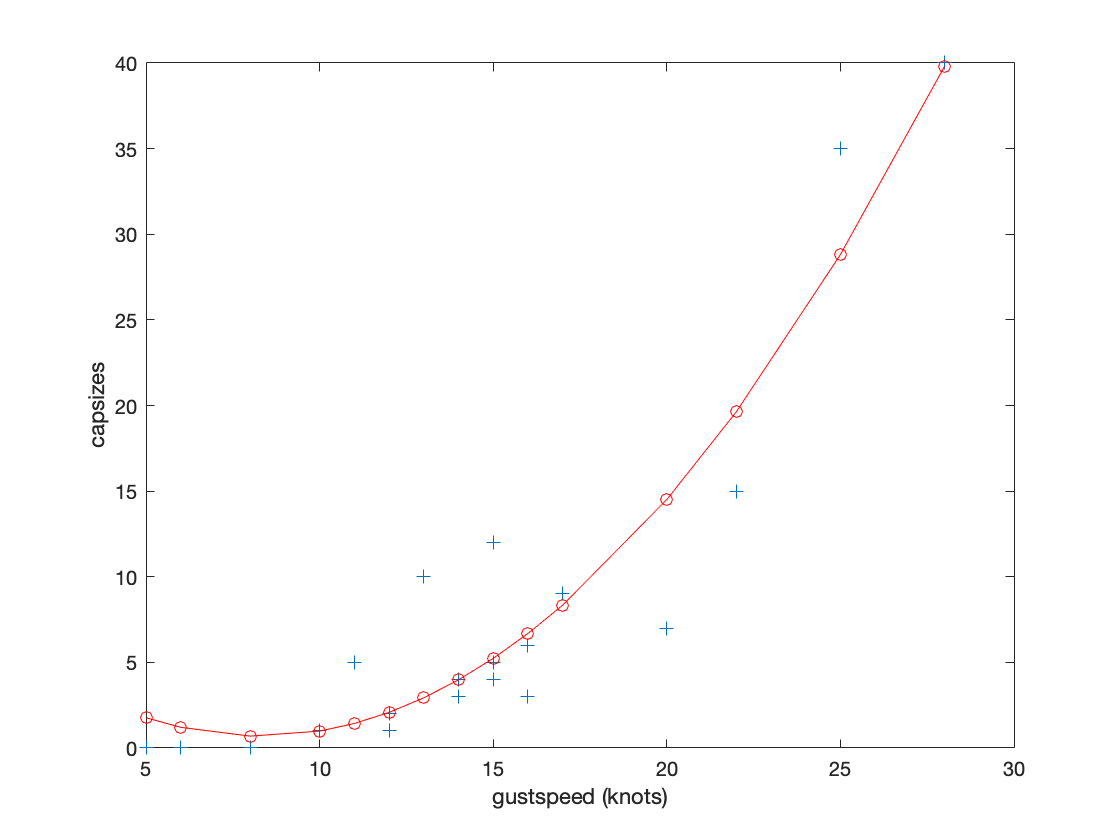


%polynomial power 2 gustspeed
figure;
X = [ones(length(GS),1) GS GS.^2];
B_hat = inv(X'*X)*X'* CS;
capsizes_hat= X*B_hat;
plot(GS, CS, '+') % plot the data
hold on;
plot(GS, capsizes_hat, '-ro') % Plot the regression line
xlabel("gustspeed (knots)")
ylabel("capsizes")

R2=1-sum(((X*B_hat) -CS).^2)/sum((CS-mean(CS)).^2)

R2 = 0.8900


%3d fit power 2 windspeed and gustspeed vs capsizes
figure;
X=[ones(size(windspeed,1),1) windspeed windspeed.^2 gustspeed gustspeed.^2];  % Form a model matrix
[Q,R] = qr(X,0); % Compute the QR decomposition of X
B_hat = R \ (Q'* capsizes); % Compute the parameters of the regression eqn
figure(4);
plot3(windspeed, gustspeed, capsizes, ' +b') % Plot the data
hold on;
capsizes_hat= X*B_hat;  % Compute the "predicted" values of wear
plot3(windspeed, gustspeed, capsizes, 'ro') % Plot the "predicted" values
[windspeedplot, gustspeedplot]= meshgrid(0:100:700, 0:5:45);
WS = linspace(0,20)';
GS = linspace(0,30)';
[WSgrid GSgrid] = meshgrid(WS,GS);
CS_func = @(windspeed, gustspeed) B_hat(1)+B_hat(2)*(windspeed)+B_hat(3)*(windspeed.^2)+B_hat(4)*(gustspeed)+B_hat(5)*(gustspeed.^2);
mesh(WSgrid, GSgrid, CS_func(WSgrid, GSgrid))
xlabel("windspeed (knots)")
ylabel("gustspeed (knots)")
zlabel("capsizes")
R2 = 1-sum(((capsizes_hat)-capsizes).^2)/sum((capsizes-mean(capsizes)).^2)

R2 = 0.9018

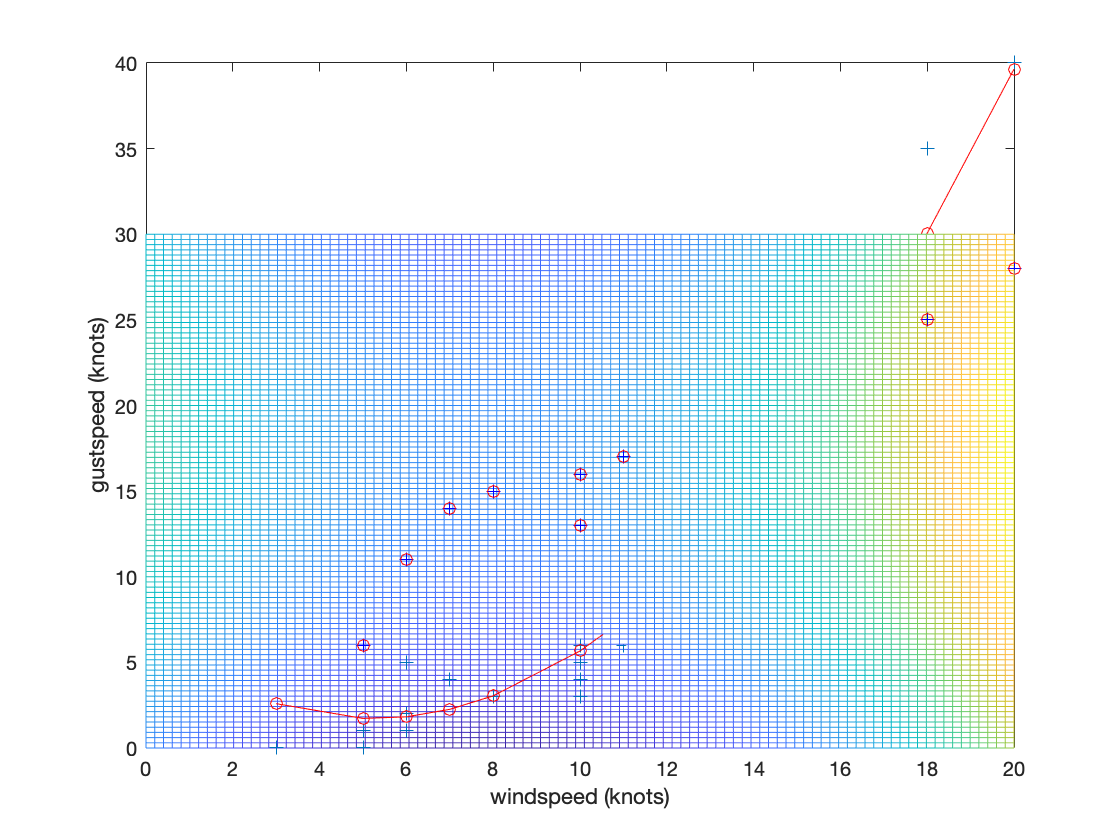

hold off;

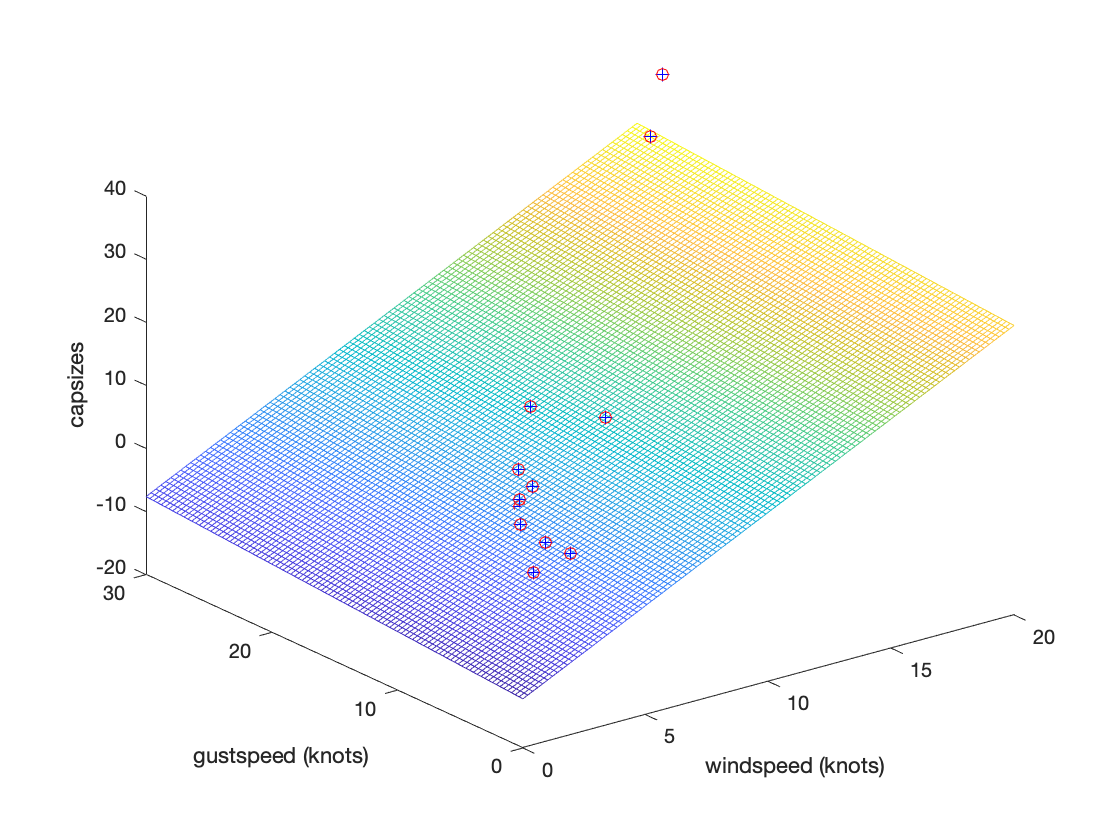


%3d fit power 1 windspeed and gustspeed vs capsizes
figure;
X=[ones(size(windspeed,1),1) windspeed gustspeed];  % Form a model matrix
[Q,R] = qr(X,0); % Compute the QR decomposition of X
B_hat = R \ (Q'* capsizes); % Compute the parameters of the regression eqn
figure(4);
plot3(windspeed, gustspeed, capsizes, ' +b') % Plot the data
hold on;
capsizes_hat= X*B_hat;  % Compute the "predicted" values of wear
plot3(windspeed, gustspeed, capsizes, 'ro') % Plot the "predicted" values
[windspeedplot, gustspeedplot]= meshgrid(0:100:700, 0:5:45);
WS = linspace(0,20)';
GS = linspace(0,30)';
[WSgrid GSgrid] = meshgrid(WS,GS);
CS_func = @(windspeed, gustspeed) B_hat(1)+B_hat(2)*(windspeed)+B_hat(3)*gustspeed;
mesh(WSgrid, GSgrid, CS_func(WSgrid, GSgrid))
xlabel("windspeed (knots)")
ylabel("gustspeed (knots)")
zlabel("capsizes")

R2 = 1-sum(((capsizes_hat)-capsizes).^2)/sum((capsizes-mean(capsizes)).^2)

R2 = 0.7563

D. Our fourth task was to calculate the probability of being in an area where if you capsized, you would get mud on your sail. This would happen in sections where the depth is the same or less than the mast height of the MIT sailing team boats. With the following two facts, this calculation was fairly straight-forward:

- The MIT sailing team uses "FJ"s with a mast height of 5 meters and "Laser"s with a mast height of 6.1 meters.

- The area they practice in is in between the Harvard Bridge and the Longfellow Bridge which is equivalent to the data we have loaded. 

capprob(3,5,20,CS_func) %example of probability of capsize with windspeed of 3 and gustspeed of 5 and 20 sailors

ans = 0

capsize_probability = capprob(20,20,30,CS_func) %example of probability of capsize with windspeed of 20 and gustspeed of 20 and 30 sailors

capsize_probability = 0.9643

Our final task was to combine these two probabilities by calculating the product of the two which gives us the total probability of capsizing and getting mud on your sail on a tipical MIT sailing team practice.

depth = finddepth(-71.1106,42.3858,relevant_x,relevant_y,relevant_z,cellsize)

depth = 1.3189

mudprob(depth,capsize_probability,"FJ") %example of probability of mud with above conditions at coordinate (-71.1,42.37) on an FJ

ans = 0.9643

### 4. Suggestions for Expanding the Project:

Because none of us have taken fluid dynamics yet, we did not explore the current and flow data of the Charles River that could be a very interesting addition to this project. It would be interesting to know the calculated currents at various points of the river based on cross-sectional area and guestimates of water input, we could also relate this data back to amore complex probability function of capsizing a boat.

function probability_of_capsize = capprob(windspeed, gustspeed,number_of_sailors,CS_func)
    num_capsize_expected_per_sailor = (abs(CS_func(windspeed,gustspeed)/number_of_sailors)+(CS_func(windspeed,gustspeed)/number_of_sailors))/2; %that makes any negative value 0
    if num_capsize_expected_per_sailor>1
        probability_of_capsize = 1;
    else
        probability_of_capsize = num_capsize_expected_per_sailor;
    end
end

function depth = finddepth(x,y,relevant_x,relevant_y,relevant_z,cellsize)
    leeway = cellsize/2;
    x_indices = find(relevant_x<(x+leeway)&relevant_x>(x-leeway));
    y_indices = find(relevant_y<(y+leeway)&relevant_y>(y-leeway));
    indices = intersect(x_indices,y_indices);
    depth = relevant_z(indices(1));
end

function probabilityofmud = mudprob(depth,capsize_probability,boattype)
    mastheight = 0;
    if boattype == "FJ"
        mastheight = 6.1;
    elseif boattype == "Laser"
        mastheight = 5;
    end
    if depth < mastheight
        probabilityofmud = capsize_probability;
    else
        probabilityofmud = 0;
    end
end